# **Solution for Q1**

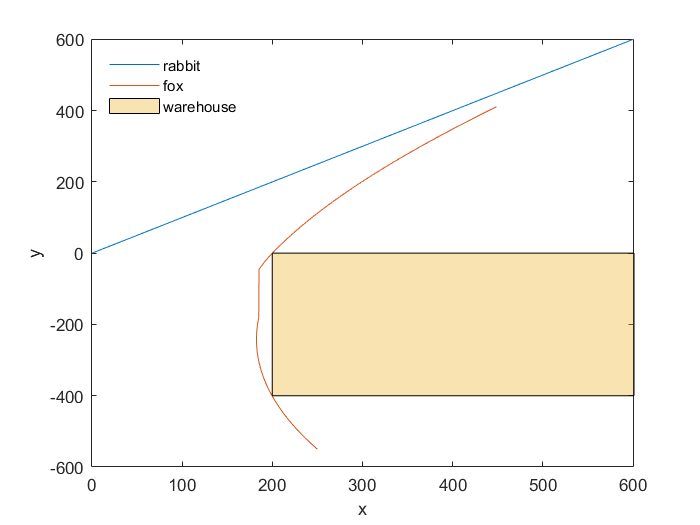

s_r = 13;%The initial speed of rabbit
s_f = 16;%The initial speed of fox
mindist = 0.1;%The distance the fox can just catch a rabbit
burrow = [600 600];%The position of the burrow
z0 = [0 0 250 -550];%The initial condition
ts = [0 norm([z0(3) z0(4)])/(s_f - s_r)];%The timespan
options=odeset('RelTol',1e-7,'AbsTol',1e-7,...
'Events',@(t,z) foxrab_events(z,mindist ,burrow));
%use the ode45 to solve the system of ODEs
[t,z,te,ze,zi] = ode45(@(t,z) foxrab_ode1(z,s_r ,s_f),ts,z0,options);
plot(z(:,1),z(:,2),z(:,3),z(:,4))%plot the track of Fox and rabbit
xlabel('x'),ylabel('y')
hold on
plot(polyshape([200 200 601 601],[-400 0 0 -400]))%plot the warehouse
%add the legend
legend({'rabbit','fox','warehouse'},'Location','northwest')
legend('boxoff')
hold off
%set the size of the plotting window
xlim([-1 601])
ylim([-600 601])


zi%Check which event was triggered

zi = 2

# **Solution for Q2**

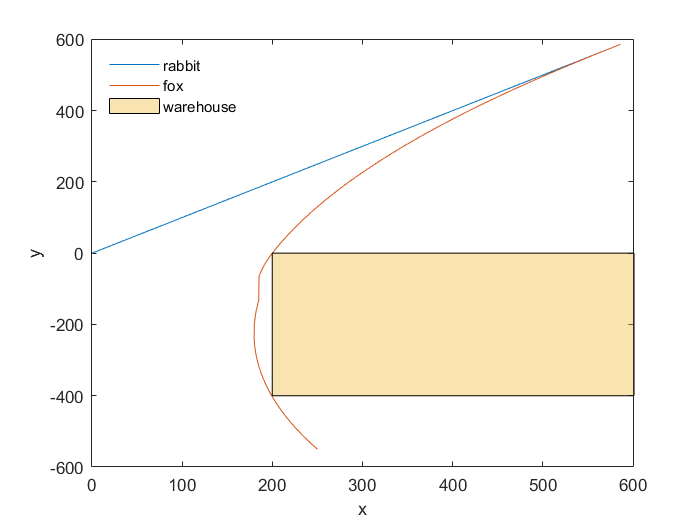

%please run Q1 first
%The last 2 elements is the initial distances traveled by fox and rabbit
z0 = [0 0 250 -550 0 0];
options=odeset(...
'RelTol',1e-7,'AbsTol',1e-7,'Events',@(t,z) foxrab_events(z,mindist ,burrow));
[t,z,te,ze,zi] = ode45(@(t,z) foxrab_ode2(z,s_r,s_f),ts,z0,options);
plot(z(:,1),z(:,2),z(:,3),z(:,4))
xlabel('x'),ylabel('y')
hold on
plot(polyshape([200 200 601 601],[-400 0 0 -400]))
%add the legend
legend({'rabbit','fox','warehouse'},'Location','northwest')
legend('boxoff')
hold off
%set the size of the plotting window
xlim([-1 601])
ylim([-600 601])

zi%Check which event was triggered

zi = 1